
% MASTER SCRIPT FOR ARMREST MODELING AND IDENTIFICATION
% FINAL VERSION WITH PARAMETER SENSITIVITY ANALYSIS (RMSE)

clear; clc; close all;


## COMPONENT CHARACTERIZATION



disp('--- SECTION 1: COMPONENT CHARACTERIZATION ---');

--- SECTION 1: COMPONENT CHARACTERIZATION ---


initial_thickness_cm = 1.0; radius_cm = 1.2 / 10;
single_pad_area_cm2 = pi * radius_cm^2; double_pad_area_cm2 = 2 * single_pad_area_cm2;
pad_calib_force_N = [0 0.8 1.6 2.4 3.3 3.7 4.1 4.9 5.7 6.5 7.7 9.0 10.6 12.2 14.3 17.2];
pad_strain = (((0:10:150) * (0.5/10))/10) / initial_thickness_cm;
pad_stress_N_cm2 = pad_calib_force_N / single_pad_area_cm2;
mechanical_fit_coeffs = polyfit(pad_strain(2:end), pad_stress_N_cm2(2:end), 1);
E_N_cm2 = mechanical_fit_coeffs(1); E_MPa = E_N_cm2 / 100;
fprintf('  Estimated Young''s Modulus (E): %.2f MPa (%.2f N/cm^2)\n', E_MPa, E_N_cm2);

  Estimated Young's Modulus (E): 4.64 MPa (464.04 N/cm^2)


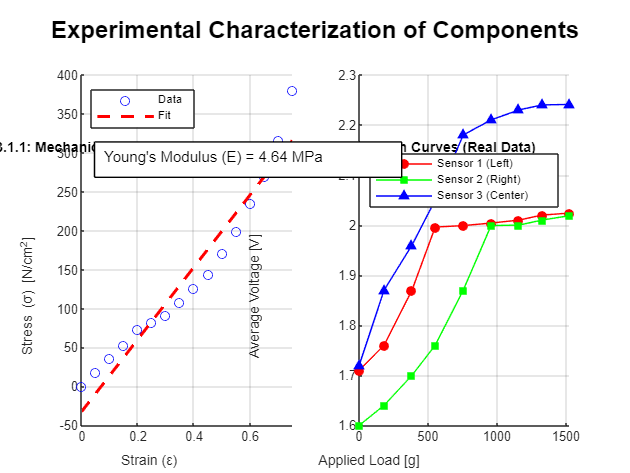


calib_weights_g = [0 180 382 550 753 954 1156 1324 1525];
voltage1_calib_V = [1.71 1.76 1.87 1.996 1.999 2.004 2.01 2.02 2.024];
weights1_calib_g = calib_weights_g;
voltage2_calib_V = [1.60 1.64 1.7 1.76 1.87 1.999 2.000 2.01 2.019];
weights2_calib_g = calib_weights_g;
voltage3_calib_V = [1.72 1.87 1.96 2.05 2.18 2.21 2.23 2.24 2.241];
weights3_calib_g = calib_weights_g;

force1_N = (weights1_calib_g / 1000) * 9.81;
theoretical_strain1 = force1_N / (E_N_cm2 * single_pad_area_cm2);
distances1_calib_cm = initial_thickness_cm - (theoretical_strain1 * initial_thickness_cm);
force2_N = (weights2_calib_g / 1000) * 9.81;
theoretical_strain2 = force2_N / (E_N_cm2 * single_pad_area_cm2);
distances2_calib_cm = initial_thickness_cm - (theoretical_strain2 * initial_thickness_cm);
force3_N = (weights3_calib_g / 1000) * 9.81;
theoretical_strain3 = force3_N / (E_N_cm2 * double_pad_area_cm2);
distances3_calib_cm = initial_thickness_cm - (theoretical_strain3 * initial_thickness_cm);

figure('Name', 'System Component Characterization');
sgtitle('Experimental Characterization of Components', 'FontSize', 16, 'FontWeight', 'bold');
subplot(1, 2, 1); hold on; grid on;
plot(pad_strain, pad_stress_N_cm2, 'ob', 'DisplayName', 'Data');
plot(pad_strain, polyval(mechanical_fit_coeffs, pad_strain), 'r--', 'LineWidth', 2, 'DisplayName', 'Fit');
xlabel('Strain (ε)'); ylabel('Stress (σ) [N/cm^2]');
%title('3.1.1: Mechanical Characterization of EVA Pad'); legend('show', 'Location', 'northwest');
text_str = sprintf('Young''s Modulus (E) = %.2f MPa', E_MPa);
annotation('textbox', [0.15, 0.6, 0.2, 0.1], 'String', text_str, 'FitBoxToText', 'on', 'BackgroundColor', 'w');
hold off;
subplot(1, 2, 2); hold on; grid on;
plot(weights1_calib_g, voltage1_calib_V, 'or-', 'MarkerFaceColor', 'r', 'DisplayName', 'Sensor 1 (Left)');
plot(weights2_calib_g, voltage2_calib_V, 'sg-', 'MarkerFaceColor', 'g', 'DisplayName', 'Sensor 2 (Right)');
plot(weights3_calib_g, voltage3_calib_V, '^b-', 'MarkerFaceColor', 'b', 'DisplayName', 'Sensor 3 (Center)');
xlabel('Applied Load [g]'); ylabel('Average Voltage [V]');
%title('3.1.2: Experimental Calibration Curves (Real Data)'); legend('show', 'Location', 'best');
hold off;

## SETUP AND EXECUTION OF SENSITIVITY ANALYSIS

disp(newline); disp('--- SECTION 2: SENSITIVITY ANALYSIS (PARAMETER SWEEP) ---');



--- SECTION 2: SENSITIVITY ANALYSIS (PARAMETER SWEEP) ---



function interp = create_sorted_interpolant(V, D)
    [V_sorted, sort_idx] = sort(V); D_sorted = D(sort_idx);
    [V_unique, unique_idx] = unique(V_sorted); D_unique = D_sorted(unique_idx);
    interp = griddedInterpolant(V_unique, D_unique, 'pchip', 'nearest');
end
V1_to_D = create_sorted_interpolant(voltage1_calib_V, distances1_calib_cm);
V2_to_D = create_sorted_interpolant(voltage2_calib_V, distances2_calib_cm);
V3_to_D = create_sorted_interpolant(voltage3_calib_V, distances3_calib_cm);
System_NonLinear_V_to_F = @(v1,v2,v3) ...
    [ (E_N_cm2*single_pad_area_cm2/initial_thickness_cm)*max(0,initial_thickness_cm-V1_to_D(v1)), ...
      (E_N_cm2*single_pad_area_cm2/initial_thickness_cm)*max(0,initial_thickness_cm-V2_to_D(v2)), ...
      (E_N_cm2*double_pad_area_cm2/initial_thickness_cm)*max(0,initial_thickness_cm-V3_to_D(v3)) ];

% Define parameter ranges to test
orders_to_test    = [2, 3, 4];
cutoffs_to_test   = [8, 10, 15, 20];
ops_to_test       = [1.8, 1.9, 1.95, 2.0];

num_combinations = length(orders_to_test) * length(cutoffs_to_test) * length(ops_to_test);
varTypes = {'double', 'double', 'double', 'double'};
varNames = {'FilterOrder', 'CutoffFreq_Hz', 'OperatingPoint_V', 'RMSE_N'};
results_table = table('Size', [num_combinations, 4], 'VariableTypes', varTypes, 'VariableNames', varNames);

dt = 0.02; fs = 1/dt; t_val = (0:dt:4)'; v_step_amplitude = 0.1;
counter = 1;

for order = orders_to_test
    for fc = cutoffs_to_test
        for V_op = ops_to_test
            [b, a] = butter(order, fc/(fs/2), 'low');
            H_filter = tf(b, a, dt);
            F_plus = sum(System_NonLinear_V_to_F(V_op+1e-6, V_op+1e-6, V_op+1e-6));
            F_minus = sum(System_NonLinear_V_to_F(V_op-1e-6, V_op-1e-6, V_op-1e-6));
            K = (F_plus - F_minus) / (2 * 1e-6);
            H_linearized = H_filter * K;
            v_input_step = V_op + (t_val >= 1) * v_step_amplitude;
            v_input_filtered = filtfilt(b, a, v_input_step);
            F_nonlinear = zeros(size(t_val));
            for i = 1:length(t_val); F_nonlinear(i) = sum(System_NonLinear_V_to_F(v_input_filtered(i), v_input_filtered(i), v_input_filtered(i))); end
            [F_linear, ~] = lsim(H_linearized, v_input_step - V_op, t_val);
            F_op_val = sum(System_NonLinear_V_to_F(V_op, V_op, V_op));
            F_linear = F_linear + F_op_val;
            idx_steady_state = t_val >= 1.5;
            error_signal = F_nonlinear(idx_steady_state) - F_linear(idx_steady_state);
            rmse = sqrt(mean(error_signal.^2));
            results_table(counter, :) = {order, fc, V_op, rmse};
            counter = counter + 1;
        end
    end
end



## RESULTS ANALYSIS AND OPTIMAL MODEL

disp(newline); disp('--- SECTION 3: RESULTS ANALYSIS AND OPTIMAL MODEL ---');



--- SECTION 3: RESULTS ANALYSIS AND OPTIMAL MODEL ---


sorted_results_table = sortrows(results_table, 'RMSE_N');
disp('Results table sorted by increasing error (best combination on top):');

Results table sorted by increasing error (best combination on top):


disp(sorted_results_table);

    FilterOrder    CutoffFreq_Hz    OperatingPoint_V    RMSE_N 
    ___________    _____________    ________________    _______

         4              20                 1.8          0.42351
         3              20                 1.8          0.42353
         2              15                 1.8          0.42354
         2              10                 1.8          0.42354
         2               8                 1.8          0.42354
         3              10                 1.8          0.42354
         3              15                 1.8          0.42354
         2              20                 1.8          0.42354
         3               8                 1.8          0.42354
         4              10                 1.8          0.42354
         4              15                 1.8          0.42354
         4               8     


optimal_params = sorted_results_table(1,:);
optimal_order = optimal_params.FilterOrder;
optimal_fc = optimal_params.CutoffFreq_Hz;
optimal_V_op = optimal_params.OperatingPoint_V;

fprintf('\n== OPTIMAL PARAMETERS FOUND ==\n');


== OPTIMAL PARAMETERS FOUND ==


fprintf('  - Filter Order: %d\n', optimal_order);

  - Filter Order: 4


fprintf('  - Cutoff Frequency: %.1f Hz\n', optimal_fc);

  - Cutoff Frequency: 20.0 Hz


fprintf('  - Operating Point: %.2f V\n', optimal_V_op);

  - Operating Point: 1.80 V


fprintf('  - Minimum RMSE: %.4f N\n', optimal_params.RMSE_N);

  - Minimum RMSE: 0.4235 N



disp('Generating analysis and validation plots with optimal parameters...');

Generating analysis and validation plots with optimal parameters...


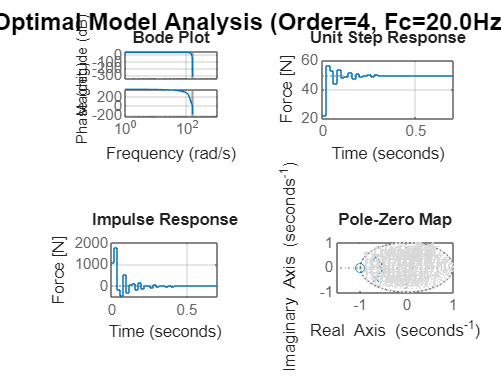

[b_opt, a_opt] = butter(optimal_order, optimal_fc/(fs/2), 'low');
H_filter_opt = tf(b_opt, a_opt, dt);
F_plus_opt = sum(System_NonLinear_V_to_F(optimal_V_op+1e-6, optimal_V_op+1e-6, optimal_V_op+1e-6));
F_minus_opt = sum(System_NonLinear_V_to_F(optimal_V_op-1e-6, optimal_V_op-1e-6, optimal_V_op-1e-6));
K_opt = (F_plus_opt - F_minus_opt) / (2*1e-6);
H_linearized_opt = H_filter_opt * K_opt;

figure('Name', 'Analysis of the Optimal Linearized Model');
sgtitle(sprintf('Optimal Model Analysis (Order=%d, Fc=%.1fHz)', optimal_order, optimal_fc), 'FontSize', 16, 'FontWeight', 'bold');
subplot(2,2,1); bode(H_linearized_opt); grid on; title('Bode Plot');
subplot(2,2,2); step(H_linearized_opt); grid on; title('Unit Step Response'); ylabel('Force [N]');
subplot(2,2,3); impulse(H_linearized_opt); grid on; title('Impulse Response'); ylabel('Force [N]');
subplot(2,2,4); pzmap(H_linearized_opt); grid on; title('Pole-Zero Map');

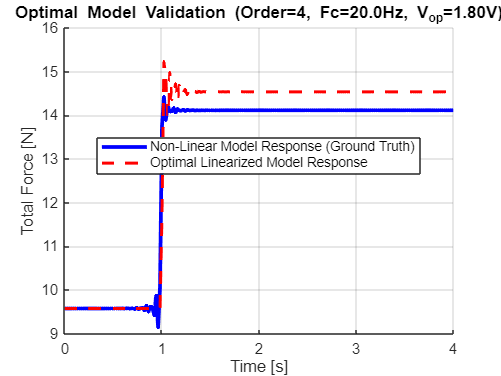


v_input_step_opt = optimal_V_op + (t_val >= 1) * v_step_amplitude;
v_input_filtered_opt = filtfilt(b_opt, a_opt, v_input_step_opt);
F_nonlinear_opt = zeros(size(t_val));
for i = 1:length(t_val); F_nonlinear_opt(i) = sum(System_NonLinear_V_to_F(v_input_filtered_opt(i), v_input_filtered_opt(i), v_input_filtered_opt(i))); end
[F_linear_opt, ~] = lsim(H_linearized_opt, v_input_step_opt - optimal_V_op, t_val);
F_op_opt = sum(System_NonLinear_V_to_F(optimal_V_op, optimal_V_op, optimal_V_op));
F_linear_opt = F_linear_opt + F_op_opt;

figure('Name', 'Validation of the Optimal Identified Model');
hold on; grid on;
plot(t_val, F_nonlinear_opt, 'b', 'LineWidth', 2.5, 'DisplayName', 'Non-Linear Model Response (Ground Truth)');
plot(t_val, F_linear_opt, 'r--', 'LineWidth', 2, 'DisplayName', 'Optimal Linearized Model Response');
xlabel('Time [s]'); ylabel('Total Force [N]');
%title_str = sprintf('Optimal Model Validation (Order=%d, Fc=%.1fHz, V_{op}=%.2fV)', ...
%                     optimal_order, optimal_fc, optimal_V_op);
%title(title_str);
legend('show', 'Location', 'best');
hold off;